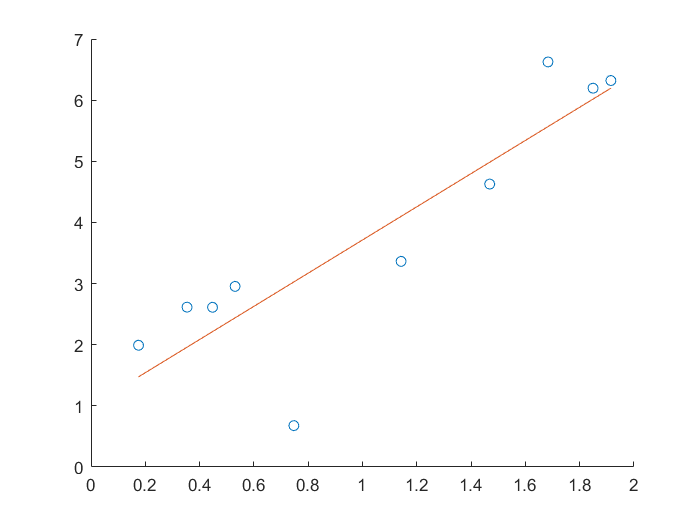

% data size
n = 10;

% generate data
a = 3;
b = 1;
x = 2*rand(n,1);
y = a*x + b + randn(n,1);
x_mean = mean(x);
y_mean = mean(y);

% LS
syms m
D_LS = sum((m*(x-x_mean) + (y-y_mean)).^2) ;
delta = diff(D_LS, m);
m_value = double(solve(delta==0, m));
y_LS = -m_value*(x-x_mean) + y_mean;
scatter(x,y), hold on
plot(x, y_LS), hold off

d_LS = double(subs(D_LS, m, m_value)) / (1+m_value^2)

d_LS = 1.0134

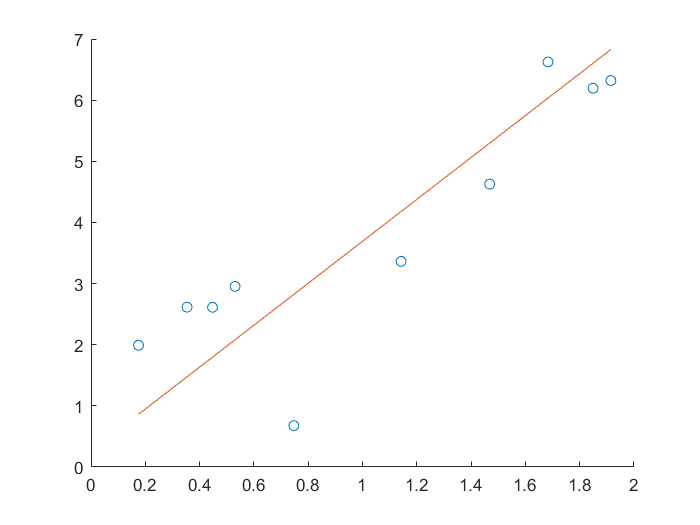


% TLS
M = [(x-x_mean) (y-y_mean)];
[P, D] = eig(M'*M);
[D_sort,index] = sort(diag(D),'descend');
D_sort = D_sort(index);
P_sort = P(:,index);
y_TLS = -P_sort(1,2)*(x-x_mean)/P_sort(2,2) + y_mean;
scatter(x,y), hold on
plot(x, y_TLS), hold off

d_TLS = norm(M*P_sort(:,2))^2

d_TLS = 0.8225